# Aeropéndulo Doble

### Amelia Hoyos, Esteban Álvarez, Gabriela Sandoval, Natalia Gómez

El sistema del aeropéndulo doble consiste en una barra rígida sujeta a un pivote en cuyos extremos están acoplados dos motores con hélices. Cada hélice genera una fuerza de empuje perpendicular a la barra, la cual induce un momento de fuerza que hace girar el sistema alrededor de su pivote, ubiccado en el origen del sistema de referencia. 

Supongamos que la fuerza de empuje $T_1$ genera un momento positivo $\vec{M}_1 = l_1 \times T_1$ y que $T_2$ genera un momento negativo $\vec{M}_2 = l_2 \times T_2$. El centro de gravedad del sistema puede no coincidir con el pivote, por lo que el peso del aeropéndulo también produce un momento de fuerza. Dicho momento viene dado por $\vec{M_3} = mgd\sin(\phi)  $, donde $g$ es la aceleración debida a la gravedad, $m$ es la masa del péndulo, $d$ es la distancia desde el pivote hasta el centro de gravedad, y $\phi$ es el ángulo positivo medido entre el eje $y$ negativo y el eje del péndulo. 

Por último, la fuerza de arrastre del aire, que se opone al movimiento, se modela mediante el término $\vec{M_4} = -b\dot{\theta}$ donde $b$ es el coeficiente de amortiguamiento viscoso del aire, $\theta = \frac{\pi}{2} - \phi$ es el ángulo medido respecto a la horizontal positiva y $\dot{\theta}$ es su velocidad angular.

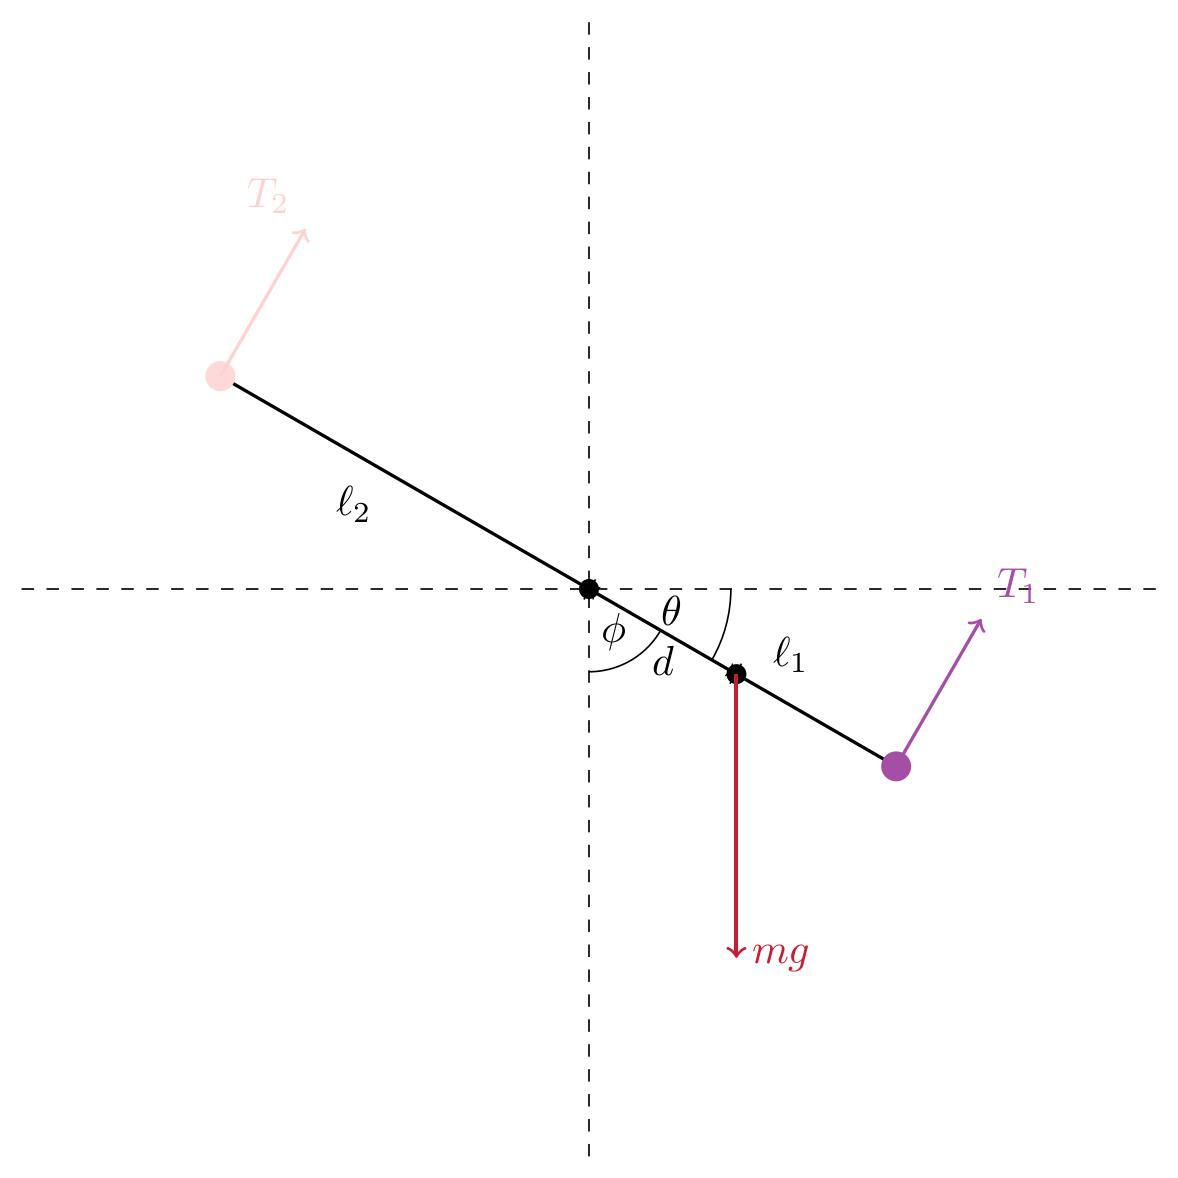

Según la formulación de Newton-Euler que describe la dinámica de sólidos rígidos, 

$J\ddot{\theta} = \sum_{i=1}^4 \vec{M_i} $,

donde $J$ es el momento de inercia rotacional del sistema. La ecuación dinámica del sistema es,

$J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\sin(\phi) - b\dot{\theta}$.

Podemos reescribir la ecuación como

$J\ddot{\theta} = T_1l_1 - T_2l_2 - mgd\cos\left( \theta\right) - b\dot{\theta}$.

## Simulación del sistema dinámico

Definimos algunos parámetros del sistema.

clear; clc; close all;
%% Physical parameters
params.m = 0.5;        % Mass (kg)
params.l1 = 0.4;       % Distance to rotor 1 (m)
params.l2 = 0.2;       % Distance to rotor 2 (m)
params.d  = 0.1;       % Distance to CG (m)
params.g  = 9.81;      % Gravity (m/s^2)
params.c  = 0.1;       % Damping coefficient (N·m·s/rad)
params.J  = params.m*(params.l1^2 + params.l2^2)/3; % Moment of inertia
%% Time span
tspan = linspace(0,10,500);

%% Initial conditions 
theta0 = 0;           % Position in rad
theta_dot0 = 0;       % Angular velocity in rad/s
x0 = [theta0; theta_dot0];

El modelo y la forma en como se define la fuerza de empuje se encuentra descrita a continuación


%% ---- Dynamics function ----
function dx = aeropendulum_dynamics(t,x,params, thrust_fun)
    theta = x(1);
    theta_dot = x(2);

    [T1,T2] = thrust_fun(t, theta, theta_dot);

    theta_ddot = (T1*params.l1 - T2*params.l2 - params.m*params.g*params.d*sin(pi/2 - theta) - params.c*theta_dot)/params.J;
    dx = [theta_dot; theta_ddot];
end

%% ---- Thrust control ----
function [T1,T2] = thrust_control(t, theta, theta_dot)
    % This function will contain in the future the manner in which we will
    % control the thrust on two motors.
    T1 = 2;
    T2 = 2;
end


Ahora resolveremos la ecuación diferencial para realizar una simulación del modelo.

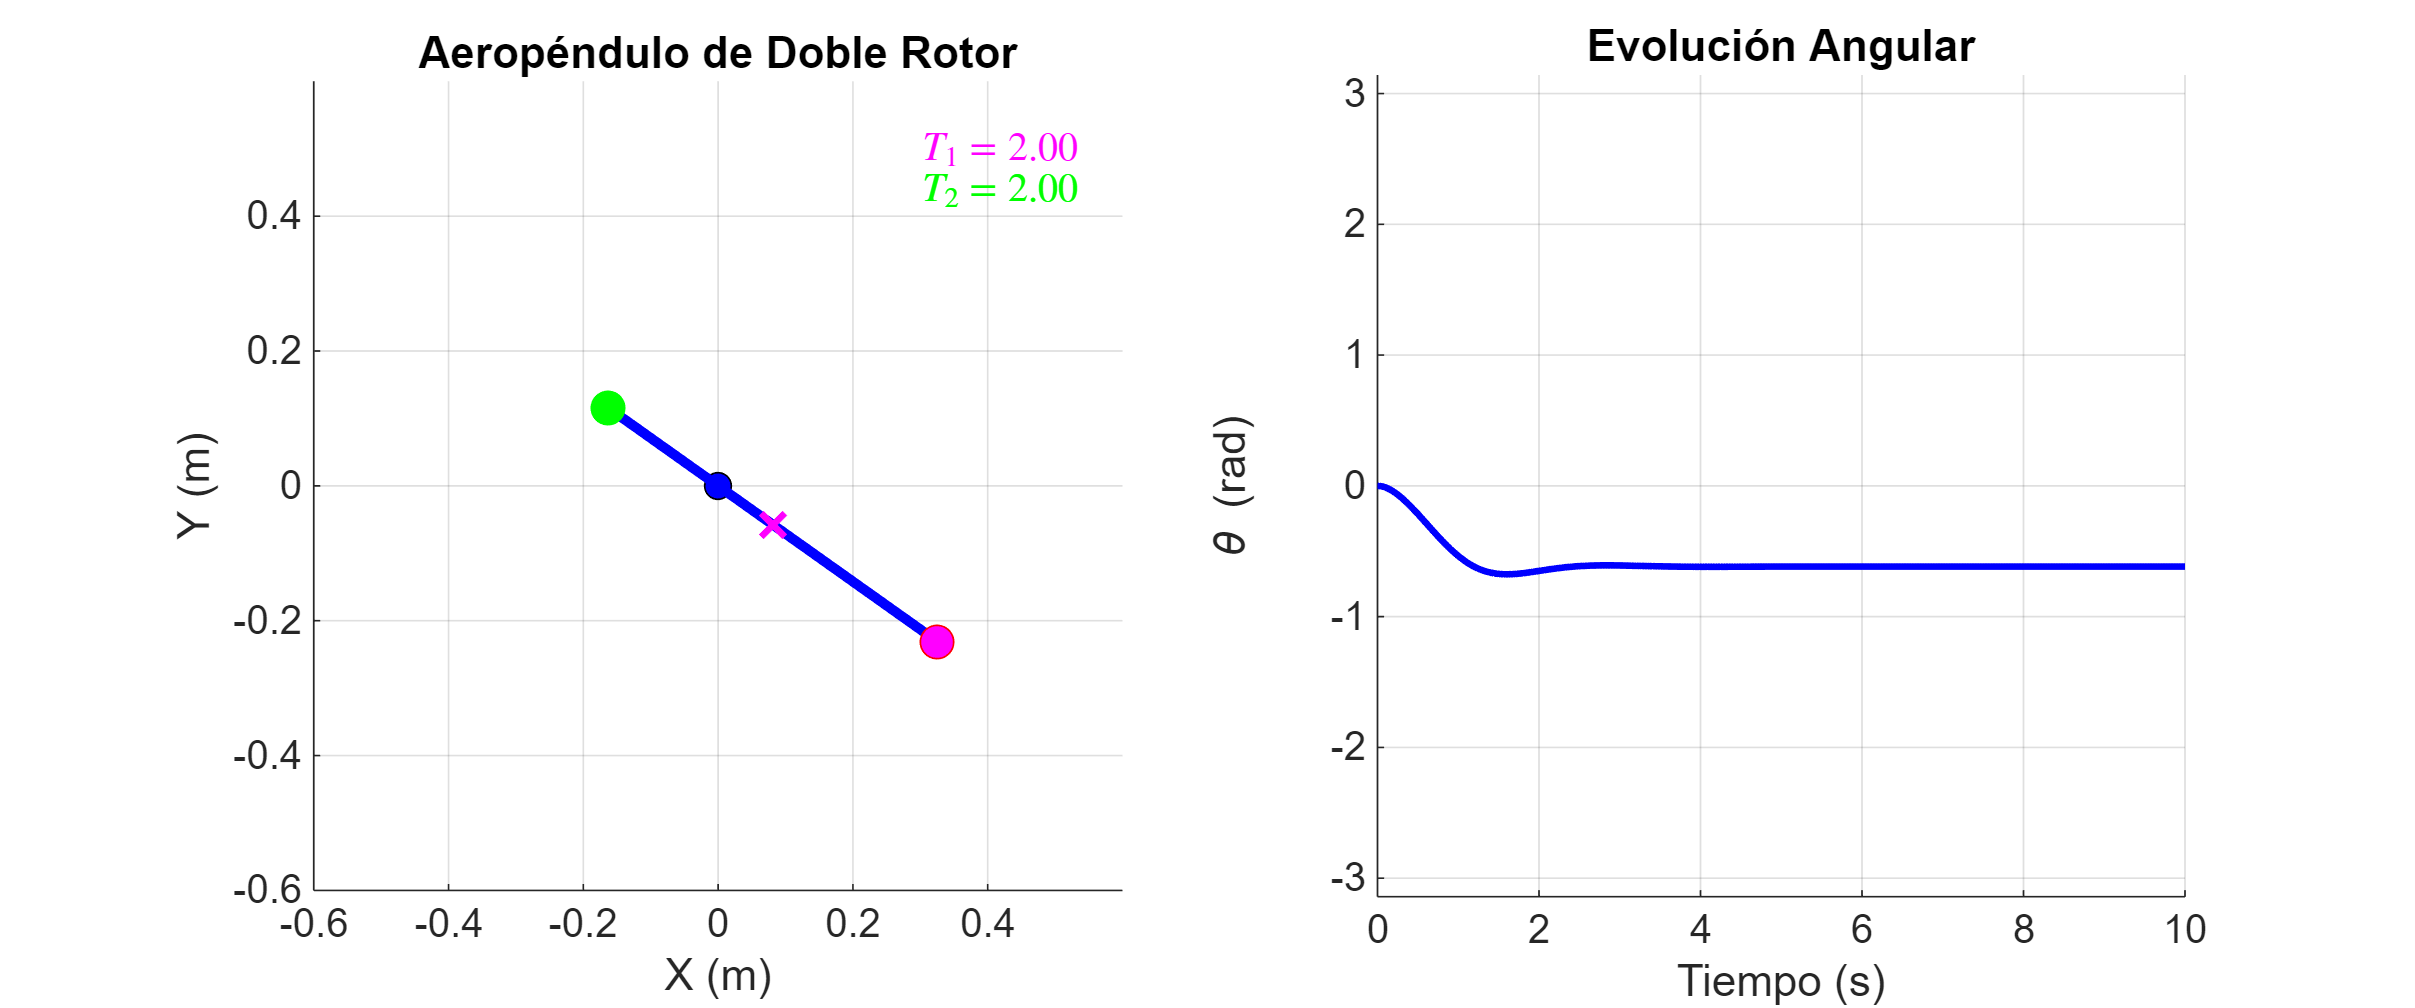

simulate_aeropendulum(@aeropendulum_dynamics, @thrust_control, params, tspan, x0)

disp("Simulation finished.")

Simulation finished.


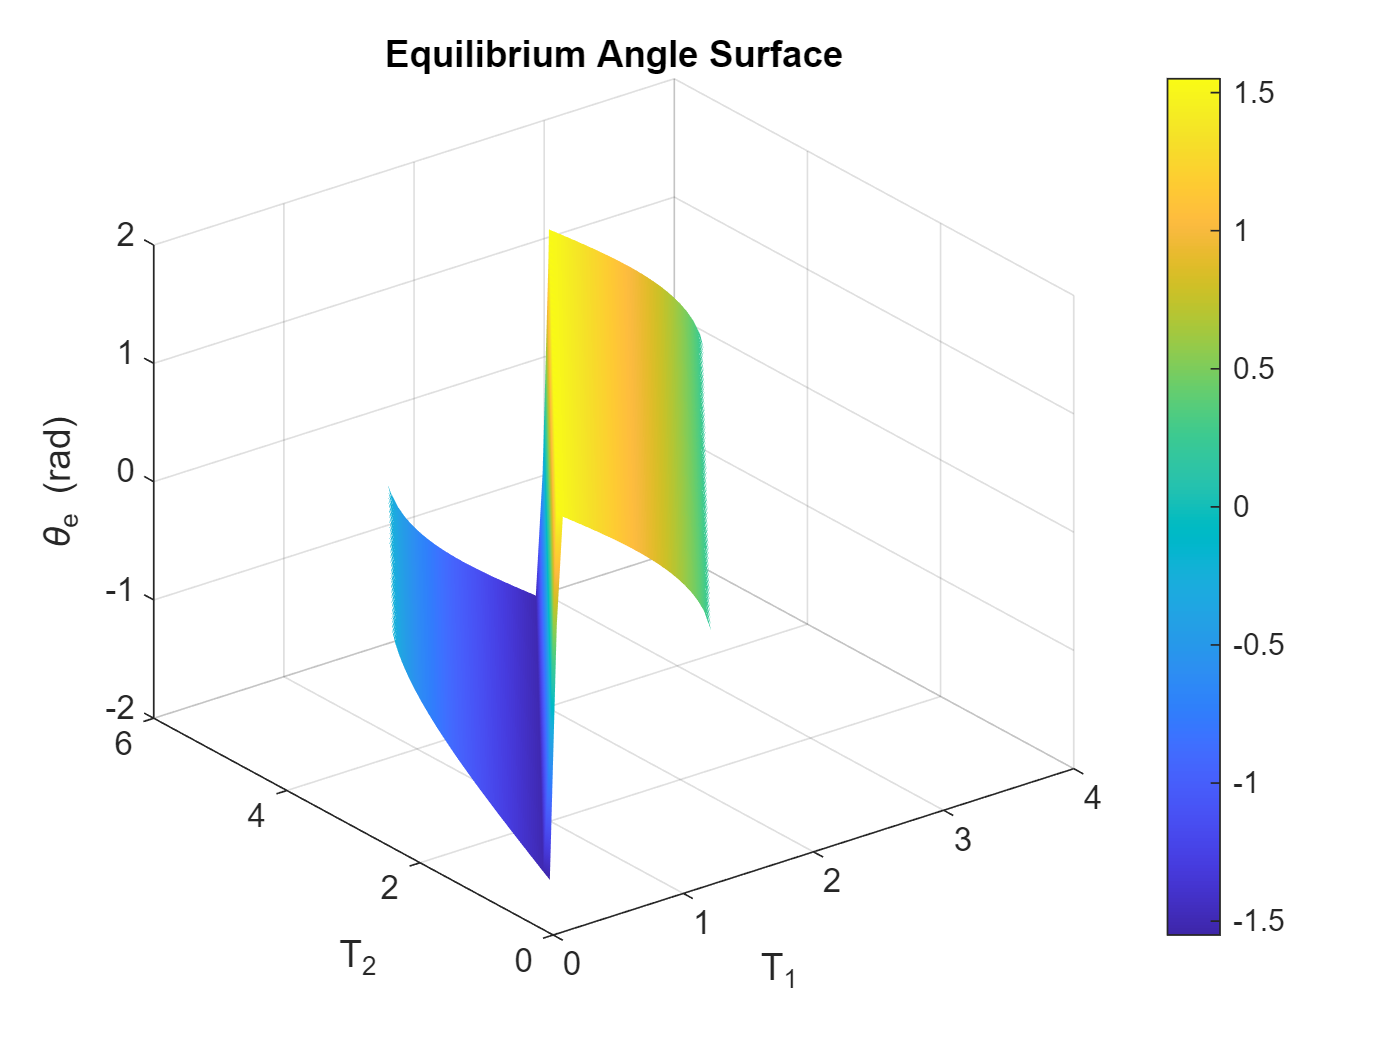

function ep = equilibrium_point(T1, T2, params)

    tau = T1*params.l1 - T2*params.l2;
    arg = tau/(params.m*params.g*params.d);

    ep = sign(tau) .* acos(abs(arg));   % elementwise

    % mask non-physical region
    ep(abs(arg) > 1) = NaN;

end
T1 = linspace(0,5,100);
T2 = linspace(0,5,100);
[T1g,T2g] = meshgrid(T1,T2);

theta_eq = equilibrium_point(T1g, T2g, params);

figure
surf(T1g, T2g, theta_eq)
shading interp
colorbar
xlabel('T_1')
ylabel('T_2')
zlabel('\theta_e (rad)')
title('Equilibrium Angle Surface')
grid on